### Include paths

addpath(genpath('lib'));
addpath(genpath('data'));
addpath('RIR_generator');
addpath('Exploration_scheme');
addpath('Echolocation');
addpath('Classification');

### Setup for RIR generator

%clearvars -except PCAFeatureMatrix
clearvars

% Utilise the stored training data
useStoredData = true;

% Defining room dimensions
RIRconstants = struct( ...
    'roomLength', 8*2, ...
    'roomWidth', 6*2, ...
    'roomHeight', 10, ...
    'robotPos', [4, 1, 4], ...
    'sampFreq', 24000, ...
    'AmountOfMicrophones', 6, ...
    'micRadius', 0.2, ...
    'SpeedofSound', 343, ...
    'micOffset', 30, ... # Notice that this is with respect to the global x-axis
    'directPathFlag', 0, ...
    'noiseWeighting', 1, ...
    'signalSDNR', 80, ...
    'signalSNR', repelem(40, 1, 6), ...
    'maximumDistance', 2, ...
    'minimumDistance', 0.5, ...
    'lengthBurst', 1500, ...
    'lengthSignal', 20000 ...
    );

setup = defaultMiscSetup([]);
setup = defaultSignalSetup(setup, RIRconstants);
setup = defaultArraySetup(setup, RIRconstants);
setup = defaultRirGenSetup(setup);
setup = defaultRoomSetup(setup, RIRconstants);
setup = defaultEmSetup(setup, RIRconstants);

setup.EM.noiseWeighting = RIRconstants.noiseWeighting;
setup.EM.plotIterations = 1; 
setup.EM.directPathFlag = RIRconstants.directPathFlag;
setup.signal.snr = RIRconstants.signalSNR;
setup.signal.sdnr = RIRconstants.signalSDNR;
setup.EM.maximumDistance = RIRconstants.maximumDistance;
setup.EM.nRefl = 1;
setup.EM.nIter = 20;

%plotRoom(setup);




### Setup for echolocation algorithm

% Struct for often used constants
echolocationConstants = struct( ...
    'Samplerate', RIRconstants.sampFreq, ...
    'AmountOfMicrophones', RIRconstants.AmountOfMicrophones, ...
    'UCARadius', RIRconstants.micRadius, ...
    'SpeedOfSound', RIRconstants.SpeedofSound, ...
    'AlphaOffset', RIRconstants.micOffset, ... 
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 601 ...
    );

% Remark for echolocationConstants:
% AlphaOffset is an offset betweeen robots LOCAL x-axis and mic 1 in degrees, 
% and is thus not the same as RIRconstants.micOffset. However, they are equal in the
% beginning, assuming zero heading angle.


% Distance parameters
MinDistance = RIRconstants.minimumDistance;
MaxDistance = RIRconstants.maximumDistance;

% Calculate angular position of microphones
echolocationConstants.Betas = UCAangles(echolocationConstants.AmountOfMicrophones, echolocationConstants.AlphaOffset);

% Define linspaces for Phis, Taus, Omegas
Phis = linspace(0, deg2rad(359), echolocationConstants.AmountOfPhis); % In rad
Taus = linspace(MinDistance, MaxDistance, echolocationConstants.AmountOfTaus) * 2 / echolocationConstants.SpeedOfSound * echolocationConstants.Samplerate; % In samples
Omegas = ceil(linspace(0, echolocationConstants.Samplerate, echolocationConstants.AmountOfOmegas)); % In Hz
OmegasAngular = Omegas * 2 * pi; % In rad/sample
OmegasAngular(ceil(echolocationConstants.AmountOfOmegas/2+1):end) = OmegasAngular(ceil(echolocationConstants.AmountOfOmegas/2+1):end) - echolocationConstants.Samplerate * 2 * pi;

% Calculate angular position of microphones
echolocationConstants.Betas = UCAangles(echolocationConstants.AmountOfMicrophones, echolocationConstants.AlphaOffset);
        
% Find the beamformer weights
SteeringVectors = SteeringVector(Phis, OmegasAngular, echolocationConstants);


### Training data

classificationConstants = struct( ...
    'numTrainingPoints', 50, ... % Should be even
    'numFeatures', 10 ... % This constant cannot be changed without changes in function CalculateFeatureVector
    );

if ~exist("FeatureMatrix") && ~useStoredData
    FeatureMatrix = ExtractFeatures(Taus, SteeringVectors, echolocationConstants, classificationConstants, RIRconstants, 'Plot', false);
    FeatureMatrix = sortrows(FeatureMatrix, 1);
else
    load("FeatureMatrix_1000_training_points.mat");
    classificationConstants.numTrainingPoints = size(FeatureMatrix,1);
end

classificationConstants.TrainingFeatures = FeatureMatrix;

### PCA Basis Transformation from 10D to 3D


% classificationConstants.featureMeans = mean(FeatureMatrix(:, 2:end), 1);
% X = FeatureMatrix(:, 2:end) - classificationConstants.featureMeans;
% X = FeatureMatrix(:, 2:end);
% minVals = zeros(1, size(X,2));
% maxVals = zeros(1, size(X,2));
% 
% for idx = 1 : size(X, 2)
%     minVals(idx) = min(X(:, idx));
%     maxVals(idx) = max(X(:, idx));
%     
%     X(:, idx) = (X(:, idx) - minVals(idx)) / (maxVals(idx) - minVals(idx));
% end
% classificationConstants.TrainingFeatures(:, 1) = FeatureMatrix(:, 1);
% classificationConstants.TrainingFeatures(:, 2:classificationConstants.numFeatures+1) = X;
% classificationConstants.minVals = minVals;
% classificationConstants.maxVals = maxVals;
% % 
% CovMatrix = cov(X);
% 
% [classificationConstants.EigenVectors, ~] = eigs(CovMatrix, 3);
% 
% PCAFeatureMatrix(:, 1) = FeatureMatrix(:, 1);
% PCAFeatureMatrix(:, 2:size(classificationConstants.EigenVectors,2)+1) = X * classificationConstants.EigenVectors;
% classificationConstants.PCATrainingFeatures = PCAFeatureMatrix;
% 
% clear minVals maxVals PCAFeatureMatrix DiagEigenValues FeatureMatrix CovMatrix

### Setup of simulation environment

% Create objects [x,y,label]

%% Create a multi-robot environment
numRobots = 3;
env = MultiRobotEnv(numRobots);
env.robotRadius = repelem(0.354/2, 1, numRobots);
env.hasObjects = true;
env.hasLidar = repelem(true, 1, numRobots);
env.showTrajectory = ones(1,numRobots);
env.robotColors = rand(numRobots,3);
env.plotSensorLines = false; % So the sensor lines don't dominate the visuals

% env.objectColors = repelem([1 0 0], numRobots, 1);
% 
% for idx = 1:numRobots
%     env.objectMarkers(idx) = '*';
% end
MaxReflectors = 30; 

objects = repelem([999 999 1], MaxReflectors, 1);
env.objectColors = repelem([1 0 0], MaxReflectors, 1);
env.objectMarkers = repelem('c', 1, MaxReflectors);


image = imread('Soundlab_map.png');
grayimage = rgb2gray(image);
bwimage = grayimage < 0.5;


% Load a map as png and apply it to the environment
resolution = size(image,1)/RIRconstants.roomWidth; % Smaller resolution corresponds to bigger map, and vice versa


grid = binaryOccupancyMap(bwimage, resolution);
%grid.GridLocationInWorld = [-width/2, -height/2];
grid.GridLocationInWorld = [0, 0];

env.mapName = "grid";


% Create robot detectors for all robots
lidars = cell(1,numRobots);
scanAngles = linspace(deg2rad(0),deg2rad(359),360);
for rIdx = 1:numRobots
    lidars{rIdx} = MultiRobotLidarSensor;
    lidars{rIdx}.robotIdx = rIdx;
    lidars{rIdx}.scanAngles = scanAngles;
    lidars{rIdx}.maxRange = 4;
end 

% Attach the defined lidar sensors to the robots
for rIdx = 1:numRobots
    attachLidarSensor(env, lidars{rIdx});
end

% Attach object detectors to the robots
% objectdetectors = cell(1,numRobots);
% for rIdx = 1:numRobots
%     objectdetectors{rIdx} = ObjectDetector;
%     objectdetectors{rIdx}.fieldOfView = 2*pi-1e-10;
%     objectdetectors{rIdx}.maxRange = 4;
%     attachObjectDetector(env,rIdx,objectdetectors{rIdx});
% end



### Setup of simulation constants

% Define time vector

stepTime = 2;
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:stepTime;  % Time array                

% Set the initial positions and orientations
radius = 1;
thetas = linspace(0, 2*pi-2*pi/numRobots, numRobots);
initialCircleCenter = [RIRconstants.roomLength/2, RIRconstants.roomWidth/2];
poses = [radius*cos(thetas) + initialCircleCenter(1); radius*sin(thetas) + initialCircleCenter(2); thetas];

% Set the speed and velocity
speed = 0.3;
vels = speed*[cos(thetas); sin(thetas); zeros(1,numRobots)];

% Set constants used as thresholds for where the robot can go
stepDist = sqrt(vels(1,1)^2 + vels(2,1)^2) * (stepTime + sampleTime);
distThresh = 0.55;

% Define the FOV as a linspace used in each direction
numAngles = 41;  % Must be uneven to get an even amount below and above 0.
scanRange = linspace(-(numAngles-1)/2, (numAngles-1)/2, numAngles);

% Defining all constants we need in the the simulation loop
explorationConstants = struct( ...
    "Height", size(image, 1)/resolution, ...
    "Width", size(image, 2)/resolution, ...
    "NumRobots", numRobots, ...
    "DistancePerStep", stepDist, ...
    "DistanceTreshold", distThresh, ...
    "DistanceMin", 0.1, ...  % Treshold for how close we can be to a point before we say it has been visited
    "Speed", speed, ...
    "TimePerStep", stepTime, ...
    "SampleTime", sampleTime, ...
    "TimeVector", tVec, ...
    "ScanRange", scanRange ...
    );


RIRconstants.roomLength = explorationConstants.Width;
RIRconstants.roomWidth = explorationConstants.Height;

## Simulation loop

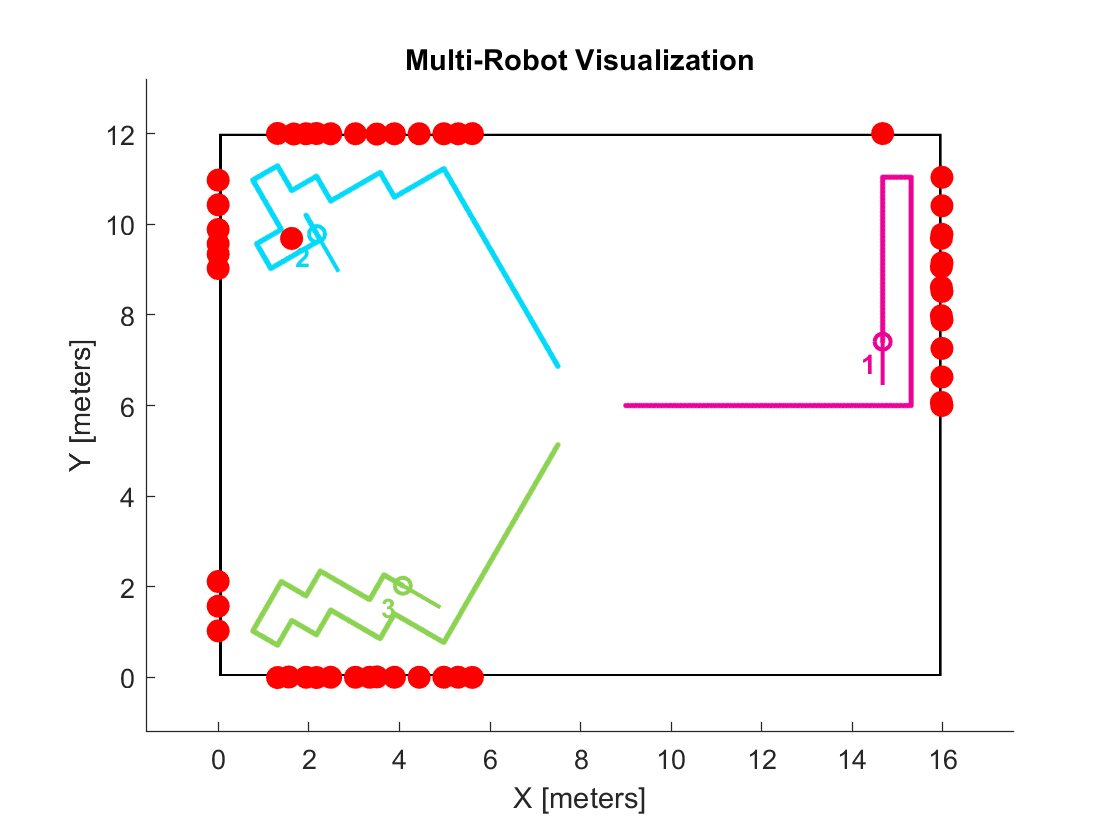

% Initialise arrays
ranges = cell(1, numRobots);
visitedPoints = zeros(1, numRobots, 2);
reflecCount = 0;

numPoints = MaxReflectors;

for k = 1:2*numPoints
    % Update the environment
    updateEnvironment(env, poses, ranges, objects, explorationConstants);
    
    for rIdx = explorationConstants.NumRobots:-1:1
        
        % Warnings are supressed temporarily, since the methods used for lidar sensor will soon be
        % deprecated and will otherwise constantly throw warnings
        warning('off')
        % Scan around the robot for objects
        scan = lidars{rIdx}();
        ranges{rIdx} = scan;
        warning('on')

        % Remember the position the robot is currently in
        visitedPoints(k, rIdx, :) = poses(1:2, rIdx);
        
        % Explore for the number of points defined
        if k <= numPoints
            
            if k > 1 
                
                RIRconstants.robotPos(1) = poses(1, rIdx); 
                RIRconstants.robotPos(2) = poses(2, rIdx);

                RIRconstants.micOffset = echolocationConstants.AlphaOffset + rad2deg(poses(3, rIdx));

                setup = defaultMiscSetup([]);
                setup = defaultSignalSetup(setup, RIRconstants);
                setup = defaultArraySetup(setup, RIRconstants);
                setup = defaultRirGenSetup(setup);
                setup = defaultRoomSetup(setup, RIRconstants);
                setup = defaultEmSetup(setup, RIRconstants);
                
                rirs = generateRirs(setup);
                signals = generateSignals(rirs,[],setup);
                ProbeSound = signals.clean;
                %disp("Robot " + rIdx);
                
                ProbeFFT = FFT(ProbeSound, "nFFT", echolocationConstants.AmountOfOmegas);
                
                % Calculate Zbar
                Zbar = CalculateZbar(ProbeFFT, Taus, echolocationConstants);
            
                [Angle, Distance] = EcholocationAlgorithm(Zbar, Phis, Taus, OmegasAngular, signals, echolocationConstants, classificationConstants, RIRconstants, ...
                    "Classification", true);
                %disp("Robot " + rIdx + ":" + Angle + ", " + Distance)
                LocalReflectorPos = [cosd(Angle) * Distance; sind(Angle) * Distance];
                
                %R = [cosd(setup.array.micOffset) -sind(setup.array.micOffset); 
                %     sind(setup.array.micOffset) cosd(setup.array.micOffset)];
                R = [cos(poses(3, rIdx)) -sin(poses(3, rIdx)); 
                    sin(poses(3, rIdx)) cos(poses(3, rIdx))];

                GlobalReflectorPos = R * LocalReflectorPos + [poses(1, rIdx); poses(2, rIdx)];
                %disp("Global pos " + rIdx + ":" + GlobalReflectorPos(1) + ", " + GlobalReflectorPos(2))
                objects(reflecCount + rIdx, :) = [GlobalReflectorPos(1), GlobalReflectorPos(2), 1];

                %plotRoom(setup);

                if rIdx == 1
                    % Increment counter used for object markers
                    reflecCount = reflecCount + numRobots;
                end

            end

            % Defining directions
            preDirecForward = getAngleBetween0and360(rad2deg(thetas(rIdx) - poses(3,rIdx)));
            preDirecLeft = getAngleBetween0and360(preDirecForward + 90);
            preDirecRight = getAngleBetween0and360(preDirecForward - 90);
            preDirecBackward = getAngleBetween0and360(preDirecForward + 180);
            
            % Determining the direction change, D, corresponding to the
            % exploration scheme
            if directionIsViable(preDirecForward, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = 0;
                
            elseif directionIsViable(preDirecLeft, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = pi/2;
                
            elseif directionIsViable(preDirecRight, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = -pi/2;
                
            elseif directionIsViable(preDirecBackward, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), explorationConstants)
                D(rIdx) = pi;
                
            else
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
            end
            
            % Find the distances to the robots with lower number than the
            % current robot
            distRobots = distanceToRobots(poses, rIdx);
            
            % We calculate the distance and angle difference to the closest robot
            [valClosestRobot, idxClosestRobot] = min(distRobots);
            angleDiff = abs(poses(3, rIdx) - poses(3, idxClosestRobot));
            
            % If another robot with higher priority is within collision distance,
            % we make the robot go back
            if valClosestRobot < stepDist*(1 - cos(angleDiff))
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
            end
            
            % Calculate the new orientation and linear velocity
            poses(3, rIdx) = thetas(rIdx) + D(rIdx);
            vels(:, rIdx) = speed*[cos(poses(3, rIdx)); sin(poses(3, rIdx)); 0];
            
            
        % Return to the beginning when we have explored for the number of
        % points defined
        else
            % Calculate the distance from the current point to the start
            distToStart = norm(poses(1:2, rIdx) - squeeze(visitedPoints(1, rIdx, :)));
            
            % If we are at the beginning, we stop
            if distToStart < explorationConstants.DistanceMin
                % Set the velocity to zero
                vels(:, rIdx) = [0; 0; 0];
            
            % Otherwise, we continue to follow the path back to the start
            else
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
                
                % Calculate the new orientation and linear velocity
                poses(3, rIdx) = thetas(rIdx) + D(rIdx);
                vels(:, rIdx) = speed*[cos(poses(3, rIdx)); sin(poses(3, rIdx)); 0];
            end
        end
    end
    
    % Simulate the robots moving with the given direction and speed
    poses = simulateMoveRobots(env, poses, vels, ranges, objects, explorationConstants);

    % Wait for x seconds
    %pause(0.3)
end